#### STEP-0: Plot the raw signal in time domain

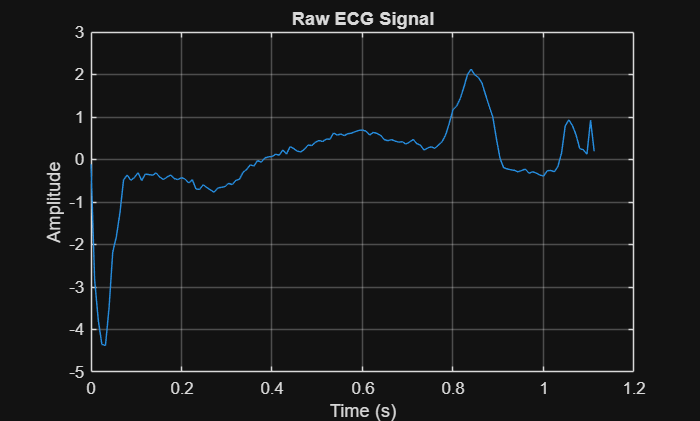

data = readmatrix('../dataset/ecg.csv');

% Take first ECG sample (row)
raw_ecg = data(1, 1:end-1);  % last column is label
raw_ecg = raw_ecg';              % convert to column vector

% Create time axis (assume sampling frequency)
fs = 125;
t = (0:length(raw_ecg)-1)/fs;

% Plot signal
%tiledlayout('flow');
%nexttile;
plot(t, raw_ecg);
title('Raw ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

%hold on;

#### STEP-1: Pre-processing to handle DC drift and inversion

The signal may be inverted based on the orientation of the ECG leads placed on the patient's body. In that case, we must rectify (vertically flip) it before passing to the ADC.

Another problem here is negative amplitudes. Most chips can't read negative amplitudes and just clip them to zero (called saturation or clipping) resulting in loss of data. W ecan avoid this by simply normalizing the amplitudes to lie between 0 and 1.

% 1. Remove DC Offset (Detrending)
% In hardware, this is a High-Pass Filter (cutoff ~0.5Hz)
clean_ecg = raw_ecg - mean(raw_ecg);

% 2. Rectify/Flip
% If the downward spike is the R-peak, we flip it.
if abs(min(clean_ecg)) > max(clean_ecg)
    clean_ecg = -clean_ecg;
end

% 3. Bias and Gain (The "INA118" Stage)
Vref = 3.3; 
signal_span = max(clean_ecg) - min(clean_ecg);
gain = (Vref * 0.8) / signal_span; 

% 4. Centering the final input to ADC
% We add Vref/2 to center the signal at 1.65V
v_adc_in = (clean_ecg * gain) + (Vref / 2); 

% 5. Hardware Clipping (Safety check)
v_adc_in = max(0, min(v_adc_in, Vref)); 

plot(t, v_adc_in);
grid on;
title('ECG (Ready for ADC Simulation)');


If we observe carefully, our signal is also R-peak aligned- the max amplitude (magnitude-wise) occurs at the beginning instead of somewhere in the middle. This is because the dataset chosen was R-peak aligned for easier processing.

Now we center our R peak horizontally as well, just to compare against a labelled diagram for visual understanding. The left-shifted (R-peak aligned) signal is more efiiceint for a chip trying to detect R-peaks, as our region of interest appears immediately, and the chip doesn't need to store the P-wave part of the signal in a buffer.

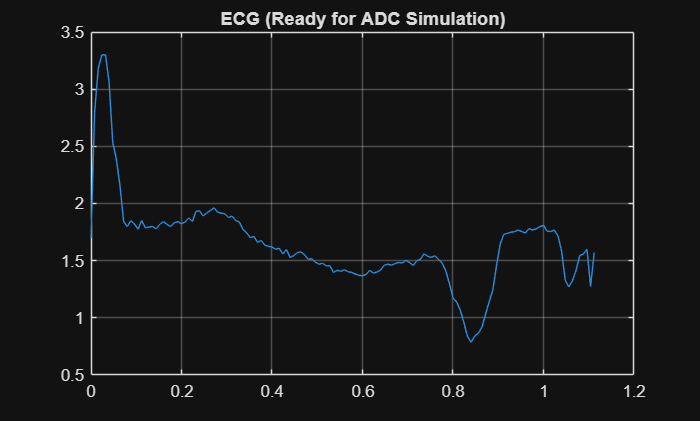

% 1. Identify the current peak location
% use clean_ecg and not touch the actual v_adc_in 
% we'll pass to the ADC
[~, max_idx] = max(clean_ecg); 

% 2. Calculate the shift needed to move the peak to the center (Index 70)
center_idx = round(length(clean_ecg) / 2);
shift_amount = center_idx - max_idx;

% 3. Circularly shift the signal
centered_ecg = circshift(clean_ecg, shift_amount);

% 4. Plot for Comparison
nexttile;

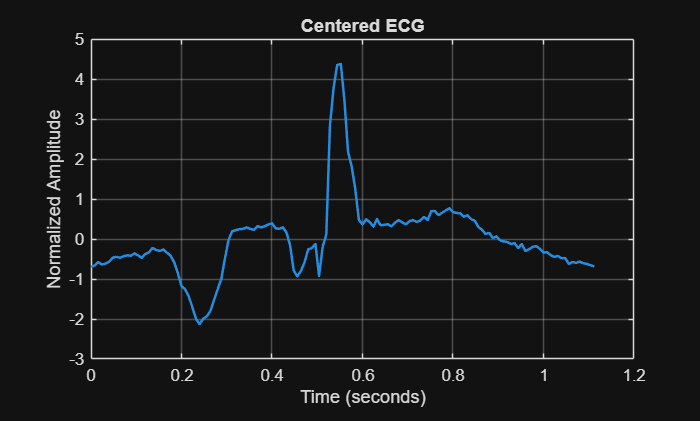

plot(t, centered_ecg, 'LineWidth', 1.5);
grid on;
title('Centered ECG');
xlabel('Time (seconds)');
ylabel('Normalized Amplitude');


% 5. Annotate the "Hardware Components" for your interview
%text(t(center_idx), 1.05, '\downarrow R-Peak (Ventricular Contraction)', 'HorizontalAlignment', 'center', 'Color', 'r');
%text(t(center_idx-25), 0.5, 'P-Wave \rightarrow', 'HorizontalAlignment', 'right');
%text(t(center_idx+30), 0.4, '\leftarrow T-Wave', 'HorizontalAlignment', 'left');


#### STEP-2: ADC Quantization

Next, we simulate **TI MSP430's 12-bit quantization **when converting an analog signal to digital. Even though our signal is digital, out hardware only has a limited precision- it can store pow(2,12) bits- or distinct values in the range [min,max] of signal amplitude. 

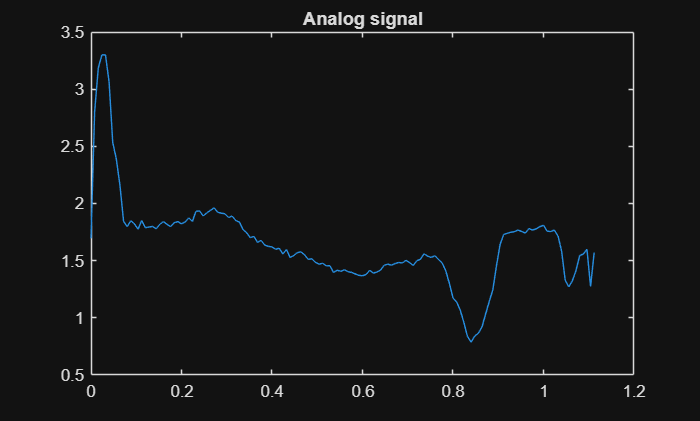

% Simulate the quantized signal
adc_levels = 2^12; 
quantized_signal = round((v_adc_in/Vref) * (adc_levels - 1));

% Calculate the "Quantization Error"
% Reconstructed voltage using quantized signal
v_reconstructed = (quantized_signal / (adc_levels - 1)) * Vref;

%the error: signal lost due to quantization
q_error = v_adc_in - v_reconstructed;

% Calculate LSB size
lsb_size = Vref / (adc_levels - 1);

% Convert error from Volts to "Number of Bits"
q_error_lsb = q_error / lsb_size;

%grid on;
figure;
plot(t, v_adc_in); title('Analog signal');

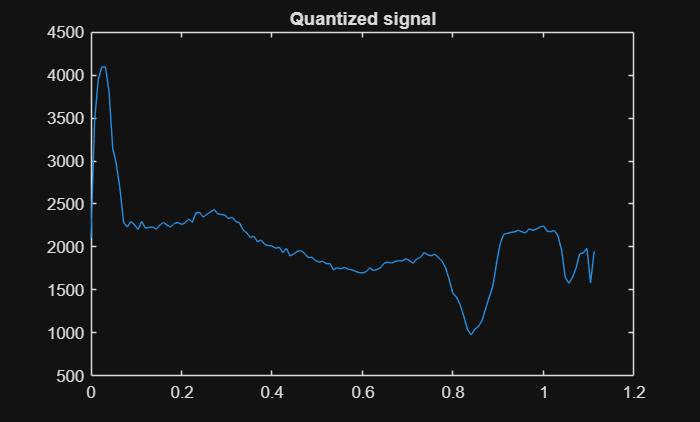

plot(t, quantized_signal); title('Quantized signal');

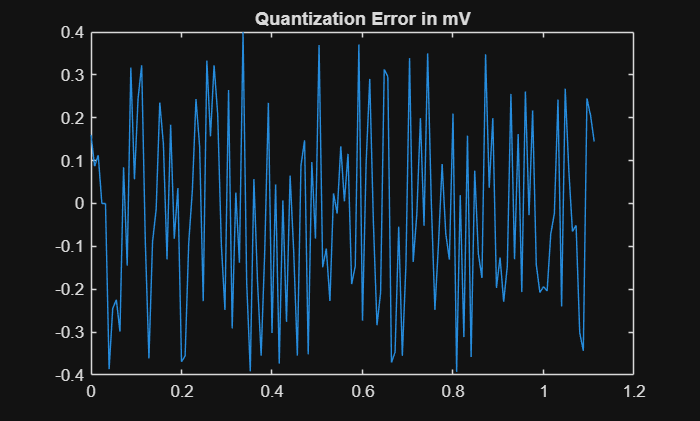

plot(t, q_error*1000); title('Quantization Error in mV');

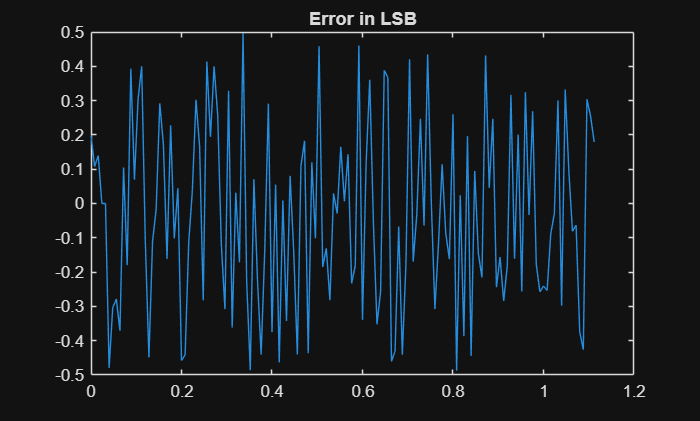

plot(t, q_error_lsb); title('Error in LSB');

STEP-3: Plot the signal in freq domain

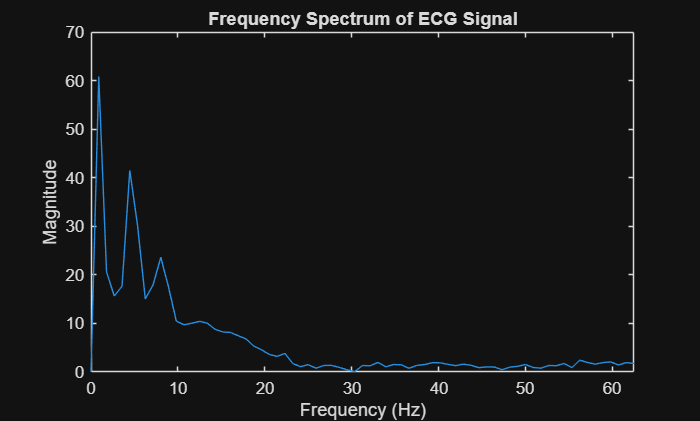

% Length of signal
N = length(ecg);

% -------- FFT --------
X = fft(ecg);

% Magnitude
X_mag = abs(X);

% Frequency axis
f = (0:N-1)*(fs/N);

% -------- Plot --------

plot(f, X_mag)

title('Frequency Spectrum of ECG Signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

xlim([0 fs/2])  % only show useful half

% Save result
saveas(gcf, '../results/frequency_spectrum_1.png')

We first plot our data in the frequency domain to understand what type of filter will help us remove noise. As we can see from the figure, there are high amplitude signals at lower frequencies (< 20 Hz). How do we know which frequencies to keep?

(1) The signal of interest is usually the high amplitude one. 

(2) Secondly, in this case we know that normal human heartbeat is around 60-100 bpm. 60 beats per minute, means 1 beat per second. 

So we are looking for a frequency around 1-2 Hz. This means we can use a **low pass filter** to keep our ECG signal and filter away the noise. 

STEP-4: Noise filtering

We implement a moving average filter. <ADD WHY, AND MATH OD HOW IT WORKS>

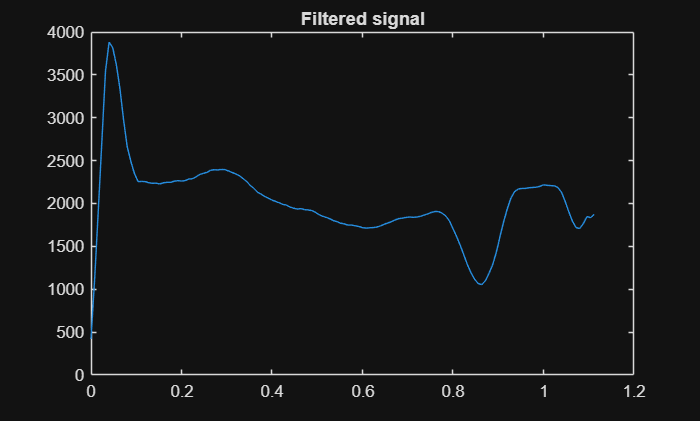

% --- 1. Define Filter Window ---
% For 125Hz, a 5-sample window is ~40ms, which smoothes noise 
% without "crushing" the sharp R-peak.
window_size = 5; 

% --- 2. Implement the Filter ---
% This simulates the DSP "Smoothing" inside the MSP430
v_filtered = filter(ones(1, window_size)/window_size, 1, quantized_signal);

% --- 3. Compensation for Filter Lag (Crucial for Engineers!) ---
% Filters introduce a small time delay. To align the plots, we shift it.
delay = floor(window_size / 2);
v_smooth = [v_filtered(delay+1:end); zeros(delay, 1)];

% --- 4. Plotting the 'Clean' Digital Data ---
figure;
plot(t, v_filtered); title('Filtered signal');

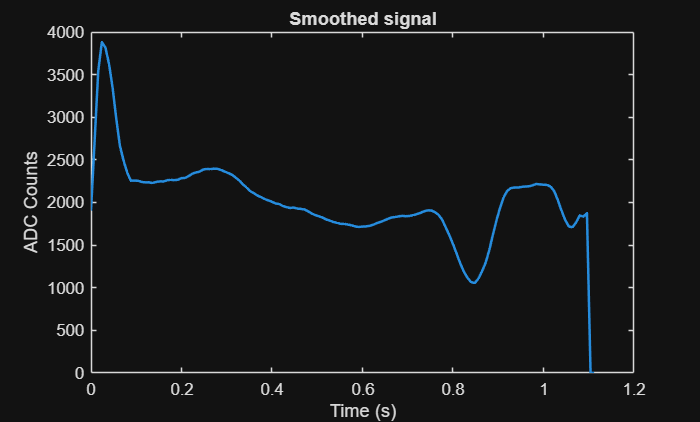

plot(t, v_smooth,'LineWidth', 1.5);
title('Smoothed signal');
xlabel('Time (s)'); ylabel('ADC Counts');

STEP-5: Peak detection

To detect peaks and caculate heartrate we need atleats two consecutive beats, or ideally a continous stream of ECG data. We construct this by joining multiplr rows of data together. 

% --- 1. Extract Heartbeat Data (Exclude last column) ---
num_beats = 10;
heartbeat_matrix = data(1:num_beats, 1:end-1); % Get 10 rows, all columns except last

% --- 2. Concatenate (Stitch) ---
% We transpose (') because MATLAB reads matrices column-wise by default.
% Reshaping ensures we have one long continuous signal.
raw_beat = reshape(heartbeat_matrix', [], 1); 

% --- 3. Diagnostics for your Report ---
Fs = 125; % From your CSV specs
total_time = length(raw_beat) / Fs;

fprintf('Total Samples: %d\n', length(raw_beat));

Total Samples: 1400


fprintf('Simulated Duration: %.2f seconds\n', total_time);

Simulated Duration: 11.20 seconds


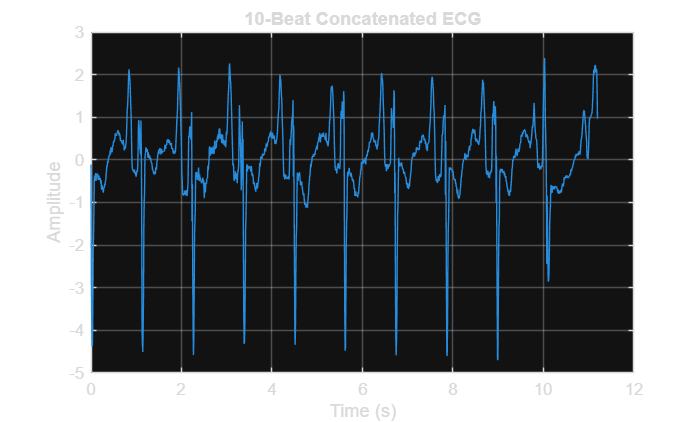


figure('Color', 'w');

plot((0:length(raw_beat)-1)/Fs, raw_beat);
title('10-Beat Concatenated ECG');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

pre-processing:

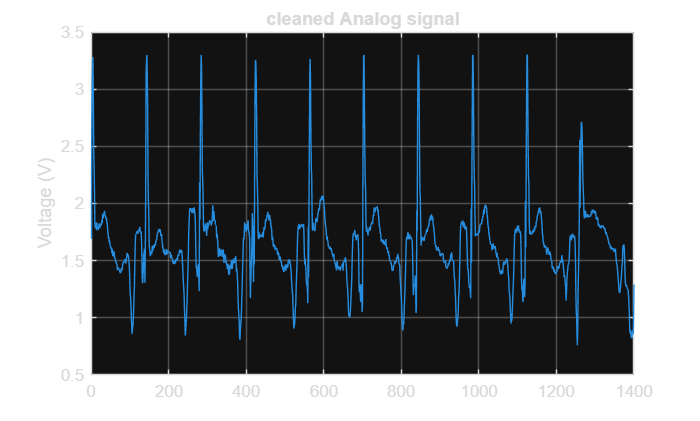

Vref = 3.3;

% Put the preprocessing code into a reusable function
v_adc_in = pre_processing(raw_beat, Vref);

% Plot to verify the flip and bias
plot(v_adc_in);
title('cleaned Analog signal');
ylabel('Voltage (V)');
grid on;

quantization:

[quantized_signal, q_error, q_error_lsb] = quantize(v_adc_in, Vref)

quantized_signal =         2099
        3352
        3789
        4055
        4067
        3651
        3054
        2887
        2625
        2268
        2215
        2275
        2242
        2190
        2276


q_error = 1.0e-03 *

    0.3480
    0.2654
    0.2041
    0.0203
    0.1279
    0.2402
    0.2237
   -0.2520
   -0.2829
   -0.1005
    0.3280
   -0.3618
    0.1590
    0.1647
    0.3133


q_error_lsb =     0.4318
    0.3294
    0.2533
    0.0252
    0.1587
    0.2981
    0.2776
   -0.3127
   -0.3511
   -0.1248
    0.4070
   -0.4490
    0.1973
    0.2044
    0.3888


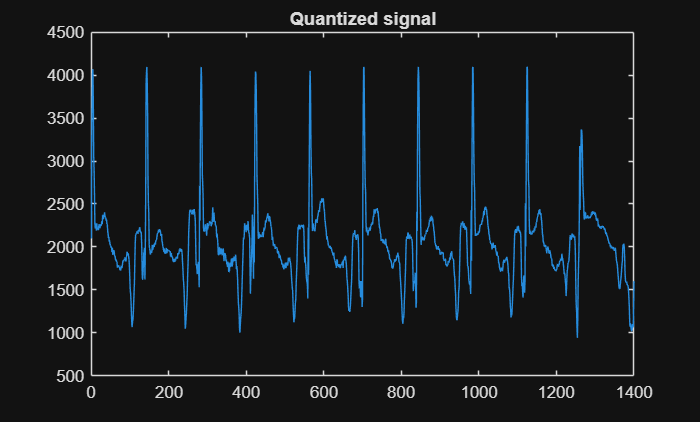

%grid on;
figure;
%plot(t, v_adc_in); title('Analog signal');
plot(quantized_signal); title('Quantized signal');

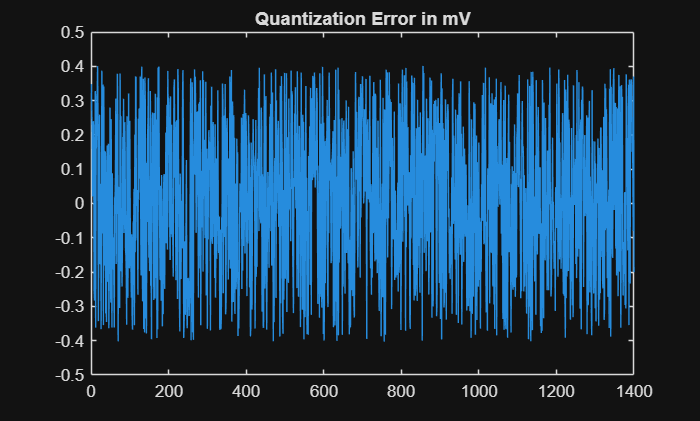

plot(q_error*1000); title('Quantization Error in mV');

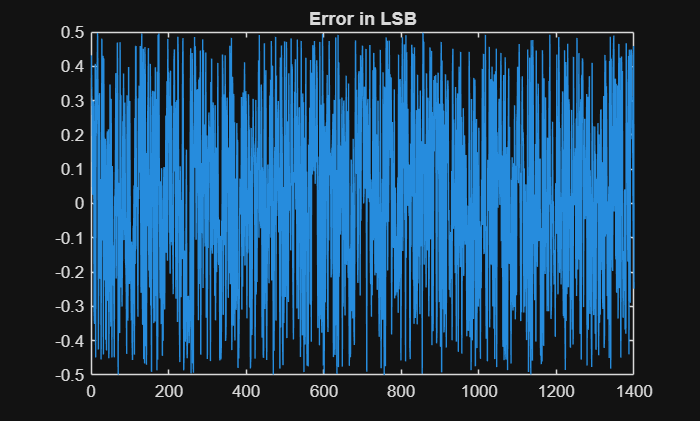

plot(q_error_lsb); title('Error in LSB');

filtering:

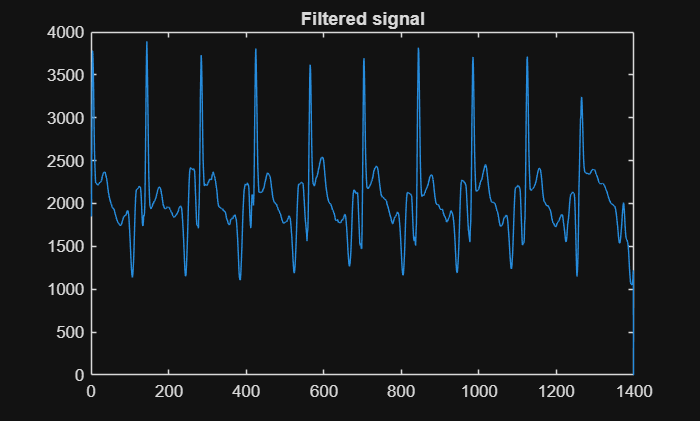

v_smooth = filter_and_smooth(quantized_signal);
plot(v_smooth); title('Filtered signal');

Calling peak detection code.

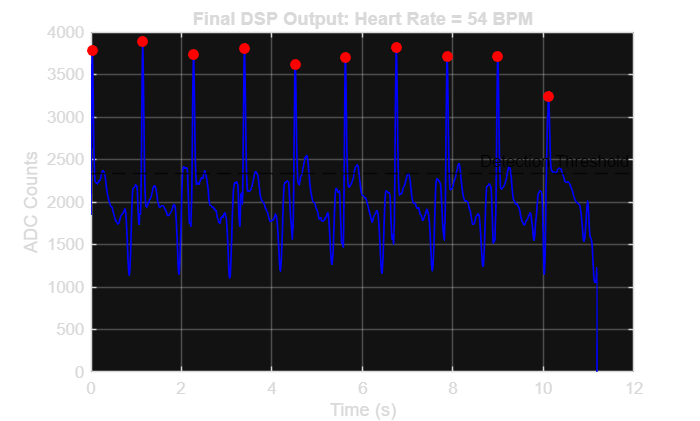

%% --- STEP 5: PEAK DETECTION (BPM LOGIC) ---

% 1. Set a Threshold
% A common rule of thumb: 60-70% of the maximum signal amplitude
threshold = 0.6 * max(v_smooth);

% 2. Find Peaks
% 'MinPeakDistance' is crucial. At 125Hz, a human heart won't beat 
% faster than ~200 BPM, so peaks must be at least 0.3s apart.
min_distance = 0.3 * fs; 
[peaks, locs] = findpeaks(v_smooth, 'MinPeakHeight', threshold, 'MinPeakDistance', min_distance);

% 3. Calculate Heart Rate (BPM)
% RR_intervals = time between peaks in samples -> converted to seconds
rr_intervals = diff(locs) / fs; 
avg_rr = mean(rr_intervals);
bpm = 60 / avg_rr;

% Plot
t = (0:length(v_smooth)-1)/fs;
figure('Color', 'w');
plot(t, v_smooth, 'b', 'LineWidth', 1); hold on;
plot(t(locs), peaks, 'ro', 'MarkerFaceColor', 'r'); % Plot red circles on peaks
yline(threshold, 'k--', 'Detection Threshold');
title(['Final DSP Output: Heart Rate = ', num2str(round(bpm)), ' BPM']);
xlabel('Time (s)'); ylabel('ADC Counts');
grid on;


% 5. Console Output (Simulating UART Telemetry)
fprintf('\n--- TI MSP430 DSP HEART RATE REPORT ---\n');


--- TI MSP430 DSP HEART RATE REPORT ---


fprintf('Calculated BPM: %.2f beats/min\n', bpm);

Calculated BPM: 53.53 beats/min


fprintf('Average R-R Interval: %.3f seconds\n', avg_rr);

Average R-R Interval: 1.121 seconds


fprintf('Total Beats Detected: %d\n', length(peaks));

Total Beats Detected: 10


fprintf('---------------------------------------\n');

---------------------------------------


We use an actual continous recording to compute this- the ANSI/AAMI EC13 data from PhysioNet.

%% --- VECTORIZED FORMAT 212 UNPACKING ---
fid = fopen(filename, 'r');
A = fread(fid, [3, inf], 'uint8')'; % Read in 3-byte chunks
fclose(fid);

% Unpack Sample 1: Byte 1 + (Low 4 bits of Byte 2)
s1 = A(:,1) + 256 * bitand(A(:,2), 15);

% Unpack Sample 2: Byte 3 + (High 4 bits of Byte 2)
s2 = A(:,3) + 256 * bitshift(A(:,2), -4);

% Reshape into a single column and convert to signed 12-bit
raw_binary = reshape([s1, s2]', [], 1);
raw_binary(raw_binary > 2047) = raw_binary(raw_binary > 2047) - 4096;

% Apply Gain (200 units/mV for aami3a)
raw_ecg = raw_binary / 200; 

% 4. Create Time Vector
Fs = 720;
t = (0:length(raw_ecg)-1) / Fs;

validating if the file was read sucessfully:

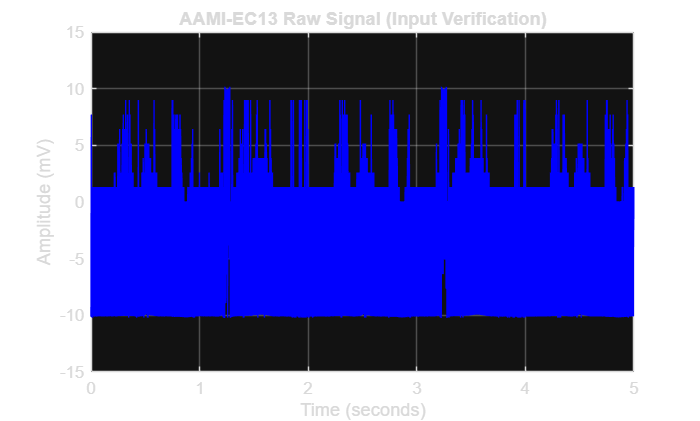

%% --- DIAGNOSTIC: DATA INTEGRITY CHECK ---
% 1. Limit to the first 5 seconds to see clear detail
t_limit = 5; 
samples_to_plot = Fs * t_limit;

% 2. Visualization
figure('Color', 'w', 'Name', 'Raw Binary Import Verification');
plot(t(1:samples_to_plot), raw_ecg(1:samples_to_plot), 'b');
title('AAMI-EC13 Raw Signal (Input Verification)');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
grid on;


% 3. Console Statistics (The "TI Engineer" Check)
fprintf('\n--- DATA INTEGRITY REPORT ---\n');


--- DATA INTEGRITY REPORT ---


fprintf('Total Samples Read: %d\n', length(raw_binary));

Total Samples Read: 57442


fprintf('Max Value (Raw): %d counts\n', max(raw_binary));

Max Value (Raw): 2047 counts


fprintf('Min Value (Raw): %d counts\n', min(raw_binary));

Min Value (Raw): -2048 counts


fprintf('Signal Duration: %.2f seconds\n', t(end));

Signal Duration: 79.78 seconds


fprintf('-----------------------------\n');

-----------------------------


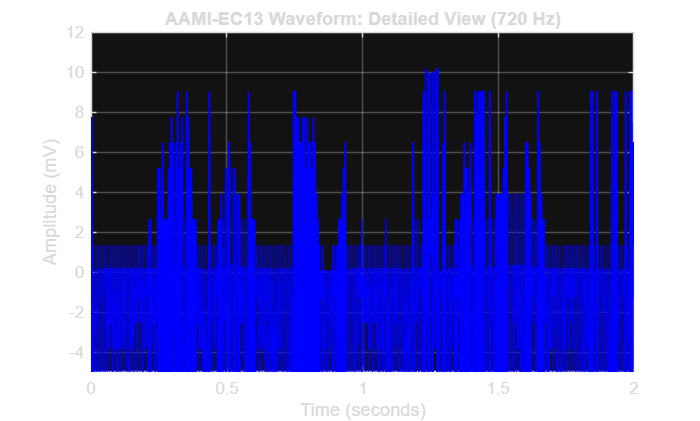


% Zoom in to see 2 heartbeats clearly
samples_to_show = Fs * 2; 

figure('Color', 'w');
plot(t(1:samples_to_show), raw_ecg(1:samples_to_show), 'b', 'LineWidth', 1.2);
title('AAMI-EC13 Waveform: Detailed View (720 Hz)');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
grid on;
ylim([-5 12]); % ECG peaks can be tall!